# Machine Learning-Based Lithium-Ion Battery Capacity Estimation Exploiting Multi-Channel Charging Profiles

In this script, we've implemented machine learning based Lithium-Ion battery capacity estimation using multi-Channel charging Profiles. Dataset used in this example is from "Battery data set" from NASA[1].

Basic implementation theory and approach is referenced by the recent published paper[2], and they proposed Multi-Channel charging profiles based machine learning and deep learning model. Throught this example, we will capture each approach described in paper.

### Multi-Channel charging profiles of V, I, T data

To observe if charging profiles shows battery aging, we need to explore Voltage(V), Current(I) and Temperature(T) path through battery aging.

In below figure, we can observe that there are significant changes in charging profiles of V, I and T as a battery ages.

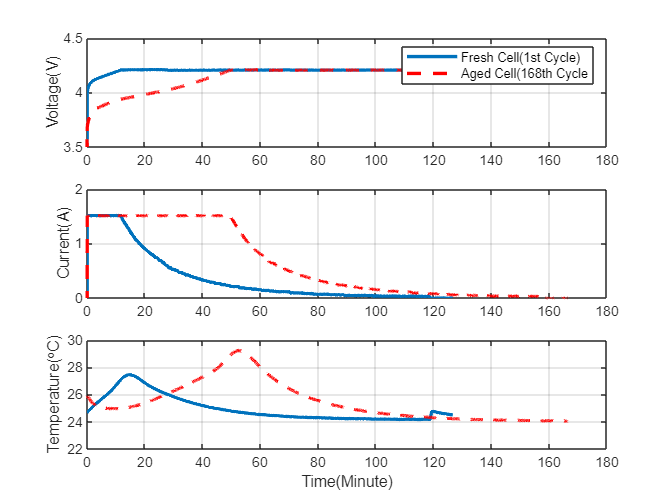

clear;
load B0005.mat
FTime = B0005.cycle(1).data.Time/60;
FreshCell_V = B0005.cycle(1).data.Voltage_measured;
FreshCell_I = B0005.cycle(1).data.Current_measured;
FreshCell_T = B0005.cycle(1).data.Temperature_measured;

ATime = B0005.cycle(168).data.Time/60;
AgedCell_V = B0005.cycle(168).data.Voltage_measured;
AgedCell_I = B0005.cycle(168).data.Current_measured;
AgedCell_T = B0005.cycle(168).data.Temperature_measured;

figure(1)
subplot(311)
plot(FTime, FreshCell_V, 'linewidth', 2), hold on, plot(ATime, AgedCell_V, 'r--','linewidth', 2)
hold off, legend('Fresh Cell(1st Cycle)', 'Aged Cell(168th Cycle'), ylabel('Voltage(V)')
ylim([3.5 4.5]), grid on
subplot(312)
plot(FTime, FreshCell_I, 'linewidth', 2), hold on, plot(ATime, AgedCell_I, 'r--', 'linewidth', 2)
hold off, ylabel('Current(A)'), ylim([0 2]), grid on
subplot(313)
plot(FTime, FreshCell_T, 'linewidth', 2), hold on, plot(ATime, AgedCell_T, 'r--', 'linewidth', 2)
hold off, ylabel('Temperature(^oC)'), ylim([22 30]), grid on, xlabel Time(Minute)

### Dataset chosen

Battery #5, #6 and #7 are chosen for the experiment. 

load B0006.mat

Error using load
Unable to find file or directory 'B0006.mat'.

load B0007.mat

Eventually, we obtain four sets of battery data with degradation characteristics per cycle as below figure.

cap5 = extract_discharge(B0005);
cap6 = extract_discharge(B0006);
cap7 = extract_discharge(B0007);
figure
plot(cap5), hold on, plot(cap6), plot(cap7)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Failure Threshold')
title('Capacity Degradations in Cycle')

### Data Preprocessing

Get ready for the training. The inputs of the proposed models in [2] are the extracted features, which are obtained by the uniform sampling of the raw battery data. Specifically, they configure the input matrix as 30-dimensional vectors by concatenating the V, I, T charging profiles, each with 10 samples. The number of samples is chosen to consider the distinct changes in time and the model complexity. In addition, we average the data over sampling interval to prevent oscillation in short time interval.

charInput5 = extract_charge_preprocessing(B0005);
charInput6 = extract_charge_preprocessing(B0006);
charInput7 = extract_charge_preprocessing(B0007);

Initial capacity for each battery data is provided as belows in the dataset:

InitC5 = 1.86;
InitC6 = 2.04;
InitC7 = 1.89;

For better training since it retains the original distribution of data except for a scaling factor and transforms all the data into the range of [0,1]:

[xB5, yB5, ym5, yr5] = minmax_norm(charInput5, InitC5, cap5);
[xB6, yB6, ym6, yr6] = minmax_norm(charInput6, InitC6, cap6);
[xB7, yB7, ym7, yr7] = minmax_norm(charInput7, InitC7, cap7);

### Machine Learning models to test

We will experiment 5 machine learning models to compare the prediction result.

Starting with FNN(Feed Forward Neural Network), we will also test CNN(Convolutional Neural Network) and LSTM(Long-Short Term Memory Network) for capacity estimation.

For FNN, we will test both for 10 and 40 hidden neurons, and also for CNN, varying the number of filter of convolution layer.

### Choose battery number to train

In the paper [2], since the available datasets are limited, among the 4 datasets, they select three battery sets as a training set and the remaining one as a test set, and repeat this process four times to have four test results. In this example, I used each dataset and divide them into train/validation/test set for generalization.

BatteryNum = 6;
switch BatteryNum
    case 5
        Train_Input = xB5;
        Train_Output = yB5;
        yr = yr5;
        ym = ym5;
    case 6
        Train_Input = xB6;
        Train_Output = yB6;
        yr = yr6;
        ym = ym6;
    case 7
        Train_Input = xB7;
        Train_Output = yB7;
        yr = yr7;
        ym = ym7;
end

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10);
netFNN10.trainParam.epochs = 300;
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind';
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

layerCNN1 = [
    imageInputLayer([1, 30]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, 30]);
    convolution2dLayer([1, 2], 30, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 15, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 5 hidden units

inputSize = 30;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

### Prediciton using each 5 trained model

Make a prediction using trained models

- FNN10

pFNN10 = netFNN10(Train_Input(tr.testInd, :)');

- FNN40

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, 30, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*yr + ym;
pFNN10 = pFNN10*yr+ ym;
pFNN40 = pFNN40*yr + ym;
pCNN1 = pCNN1*yr + ym;
pCNN2 = pCNN2*yr + ym;
pLSTM = pLSTM*yr + ym;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN10, '*--'), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.')
plot(1:25, 1.4*ones(1, 25),'k--','LineWidth', 2), xlim([1 25])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN10 Predicted', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted', 'Failure Threshold')

[1] B. Saha and K. Goebel, ``Battery data set,''NASA AMES Prognostics Data Repository, 2007.

[2] Choi, Yohwan, et al. "Machine Learning-Based Lithium-Ion Battery Capacity Estimation Exploiting Multi-Channel Charging Profiles." *IEEE Access* 7 (2019): 75143-75152.

***Copyright 2019 The MathWorks, Inc.***